# Pitch rate command system

## Create models

% Generate models
altitude = 40000;
velocity = 300;
V = velocity;  % alias
g = 9.80665;

model = find_f16_dynamics('LIN_F16Block_', 0, altitude, velocity, 5);

model.ss_lon_re = ss(model.ss_lon_ac.A([2, 4], [2, 4]), model.ss_lon_ac.B([2, 4]), ...
                     model.ss_lon_ac.C([2, 4], [2, 4]), model.ss_lon_ac.D([2, 4]), ...
                     'StateName', {'alpha', 'q'},...
                     'InputName', {'delta_e'},...
                     'OutputName', {'alpha', 'q'});

model.ss_lon_ac

ans =
 
  A = 
                   v       alpha       theta           q
   v        -0.08894       -10.7      -32.17      -3.977
   alpha  -0.0005042    -0.05167  -3.989e-14      0.9792
   theta           0           0           0           1
   q       1.228e-18     -0.6256           0     -0.2485
 
  B = 
             delta_e
   v        -0.07104
   alpha  -0.0002308
   theta           0
   q        -0.01541
 
  C = 
              v  alpha  theta      q
   v          1      0      0      0
   alpha      0      1      0      0
   theta      0      0      1      0
   q          0      0      0      1
 
  D = 
          delta_e
   v            0
   alpha        0
   theta        0
   q            0
 
Continuous-time state-space model.



model.ss_lon_re

ans =
 
  A = 
             alpha         q
   alpha  -0.05167    0.9792
   q       -0.6256   -0.2485
 
  B = 
             delta_e
   alpha  -0.0002308
   q        -0.01541
 
  C = 
          alpha      q
   alpha      1      0
   q          0      1
 
  D = 
          delta_e
   alpha        0
   q            0
 
Continuous-time state-space model.



## Compare reduced model

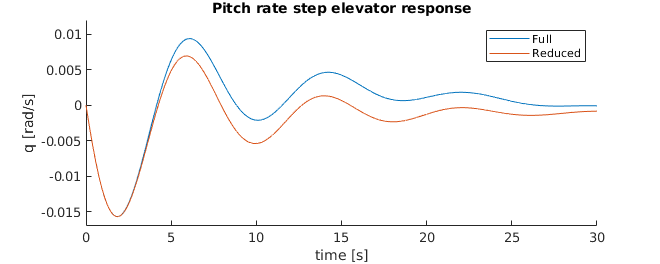

t_end = 30;
t = 0:0.001:t_end;
[y_ac, t_ac] = step(model.ss_lon_ac, t);
[y_re, t_re] = step(model.ss_lon_re, t);

[y_ac_i, t_ac_i] = impulse(model.ss_lon_ac, t);
[y_re_i, t_re_i] = impulse(model.ss_lon_re, t);

clf
hold on
plot(t_ac, y_ac(:, 4))
plot(t_re, y_re(:, 2))
xlabel('time [s]')
ylabel('q [rad/s]')
title({'Pitch rate step elevator response'})
set(gcf,'units','points','position',[0,0, 500, 200])
legend("Full", "Reduced")
xlim([0, t_end]);
ylim([-0.017, 0.012])

% hold on
% plot(t_ac_i, y_ac_i(:, 4))
% plot(t_re_i, y_re_i(:, 2))
% xlabel('time [s]')
% ylabel('q [rad/s]')
% title({'Pitch rate impulse elevator response'})
% set(gcf,'units','points','position',[0,0, 500, 300])
% legend("Full", "Reduced")
% xlim([0, t_end]);
% ylim([-0.017, 0.012])

hold off

## Tuning for natural frequency and damping

% Required natural frequencies, damping and poles
wn_required = 0.03 * velocity * 0.3048;
zeta_required = 0.5;
Ttheta2_required = 1/(0.75*wn_required);
poles_required = wn_required * [-zeta_required+sqrt(zeta_required^2 - 1)...
                                -zeta_required-sqrt(zeta_required^2 - 1)];

% place poles and create new model
K = place(model.ss_lon_re.A, model.ss_lon_re.B, poles_required)

K =  -449.0440 -151.8325



% Create new model by feeding back K. The new A matrix can be calulated by
% A_new = A-BK
model.ss_closed_re = feedback(model.ss_lon_re, K);
model.ss_closed_re

ans =
 
  A = 
            alpha        q
   alpha  -0.1553   0.9442
   q       -7.544   -2.588
 
  B = 
             delta_e
   alpha  -0.0002308
   q        -0.01541
 
  C = 
          alpha      q
   alpha      1      0
   q          0      1
 
  D = 
          delta_e
   alpha        0
   q            0
 
Continuous-time state-space model.




% Display results
damp(model.ss_lon_re);

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.50e-01 + 7.76e-01i     1.90e-01       7.91e-01         6.66e+00    
 -1.50e-01 - 7.76e-01i     1.90e-01       7.91e-01         6.66e+00    


poles_required

poles_required =   -1.3716 + 2.3757i  -1.3716 - 2.3757i


damp(model.ss_closed_re);

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.37e+00 + 2.38e+00i     5.00e-01       2.74e+00         7.29e-01    
 -1.37e+00 - 2.38e+00i     5.00e-01       2.74e+00         7.29e-01    



% Apply feedback on AC model
Kac = [0 K(1) 0 K(2)];
model.ss_closed_ac = feedback(model.ss_lon_ac, Kac);
damp(model.ss_closed_ac)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -4.17e-02 + 1.21e-01i     3.26e-01       1.28e-01         2.40e+01    
 -4.17e-02 - 1.21e-01i     3.26e-01       1.28e-01         2.40e+01    
 -1.37e+00 + 2.37e+00i     5.02e-01       2.74e+00         7.28e-01    
 -1.37e+00 - 2.37e+00i     5.02e-01       2.74e+00         7.28e-01    


## Gust

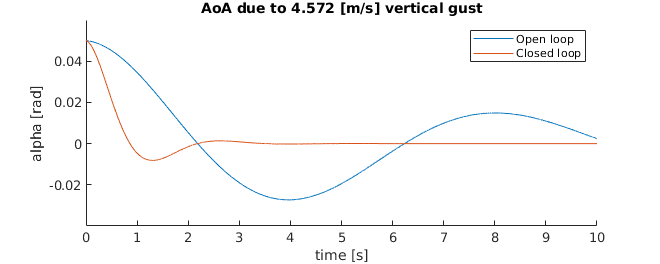

v_gust = 4.572;
t_end = 10;
alpha_gust = 4.572 / (velocity * 0.3048);

x0 = [alpha_gust 0];
[yt, tt] = initial(model.ss_closed_re, x0, 0:0.001:t_end);
[y, t] = initial(model.ss_lon_re, x0, 0:0.001:t_end);

clf
hold on
plot(t, y(:, 1));
plot(tt, yt(:, 1));
xlabel('time [s]')
ylabel('alpha [rad]')
title({'AoA due to 4.572 [m/s] vertical gust'})
set(gcf,'units','points','position',[0,0, 500, 200])
legend("Open loop", "Closed loop")
xlim([0, t_end]);

s = tf('s');
[b, a] = ss2tf(model.ss_closed_re.A, model.ss_closed_re.B, model.ss_closed_re.C, model.ss_closed_re.D);
b = b(2, :) % Select q output

b =          0   -0.0154   -0.0007



Ttheta2_old = b(2) / b(3)

Ttheta2_old = 23.6417


old_zero = (1 + Ttheta2_old * s)

old_zero =
 
  23.64 s + 1
 
Continuous-time transfer function.



new_zero = (1 + Ttheta2_required * s)

new_zero =
 
  0.4861 s + 1
 
Continuous-time transfer function.




model.ss_lon_re

ans =
 
  A = 
             alpha         q
   alpha  -0.05167    0.9792
   q       -0.6256   -0.2485
 
  B = 
             delta_e
   alpha  -0.0002308
   q        -0.01541
 
  C = 
          alpha      q
   alpha      1      0
   q          0      1
 
  D = 
          delta_e
   alpha        0
   q            0
 
Continuous-time state-space model.




N1 = rscale(model.ss_lon_re.A, model.ss_lon_re.B, [0 1], [0], K)

N1 = -1.1547e+04

N2 = rscale(model.ss_lon_ac.A, model.ss_lon_ac.B, [0 0 0 1], [0], Kac)

N2 = -4.6745e+03


tf_ll_compensator = tf(new_zero / old_zero, 'InputName', "q_c")

tf_ll_compensator =
 
  0.4861 s + 1
  ------------
  23.64 s + 1
 
Continuous-time transfer function.



                      
% lead-lag Compensated Closed loop
model.ss_cc_re = minreal(N1 * tf_ll_compensator * model.ss_closed_re);
model.ss_cc_ac = minreal(N2 * tf_ll_compensator * model.ss_closed_ac);
model.ss_cc_re

ans =
 
  A = 
             alpha         q         ?
   alpha   -0.1553    0.9442  0.006901
   q        -7.544    -2.588    0.4607
   ?             0         0   -0.0423
 
  B = 
          delta_e
   alpha   0.0548
   q        3.658
   ?           16
 
  C = 
          alpha      q      ?
   alpha      1      0      0
   q          0      1      0
 
  D = 
          delta_e
   alpha        0
   q            0
 
Continuous-time state-space model.



model.ss_cc_ac

ans =
 
  A = 
                   v       alpha       theta           q           ?
   v        -0.08894       -42.6      -32.17      -14.76      0.8598
   alpha  -0.0005042     -0.1553  -3.989e-14      0.9442    0.002794
   theta           0           0           0           1           0
   q       1.228e-18      -7.544           0      -2.588      0.1865
   ?               0           0           0           0     -0.0423
 
  B = 
          delta_e
   v        6.827
   alpha  0.02218
   theta        0
   q        1.481
   ?           16
 
  C = 
              v  alpha  theta      q      ?
   v          1      0      0      0      0
   alpha      0      1      0      0      0
   theta      0      0      1      0      0
   q          0      0      0      1      0
 
  D = 
          delta_e
   v            0
   alpha        0
   theta        0
   q            0
 
Continuous-time state-space model.



## Criteria

[b, a] = ss2tf(model.ss_cc_re.A, model.ss_cc_re.B, model.ss_cc_re.C, model.ss_cc_re.D);
b = b(2, :) % Select q output

b =          0    3.6576    7.6799    0.3183


tf_q = minreal(tf(b, a))

tf_q =
 
     3.658 s + 7.525
  ---------------------
  s^2 + 2.743 s + 7.525
 
Continuous-time transfer function.



Ttheta2 = b(2) / b(3)

Ttheta2 = 0.4763

Ttheta2_required

Ttheta2_required = 0.4861


% Get parameters from the final system
[wn, zeta] = damp(model.ss_cc_ac);
wn = wn(4)

wn = 2.7390

zeta = zeta(4)

zeta = 0.5018


wn_required 

wn_required = 2.7432

zeta_required 

zeta_required = 0.5000


% The cirteria values
CAP = g * wn^2 * Ttheta2 /(velocity)

CAP = 0.1168

DBqss = Ttheta2 - 2 * zeta/(wn)

DBqss = 0.1099

### Control Anticipation Parameter

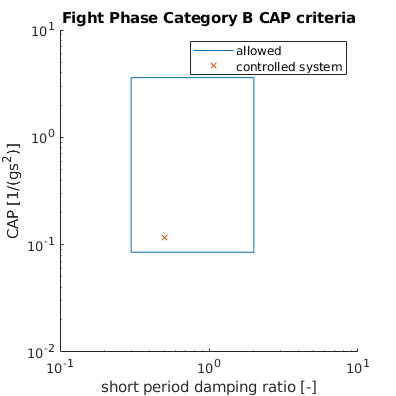

CAP_allowed_area = [0.3 0.085; 2 0.085; 2 3.6; 0.3 3.6; 0.3 0.085]; 

clf
hold on
set(gca,'xscale','log')
set(gca,'yscale','log')
plot(CAP_allowed_area(:,1), CAP_allowed_area(:,2))
plot(zeta, CAP, "x");

xlabel('short period damping ratio [-]')
ylabel('CAP [1/(gs^2)]')
title({'Fight Phase Category B CAP criteria'})
set(gcf,'units','points','position',[0,0, 300, 300])
legend("allowed", "controlled system")
ylim([0.01, 10])
xlim([0.1, 10])
hold off

### Gibson Dropback criterion

t_end = 10;

t = 0:0.01:t_end;
u = ones(1, length(t));


ss_cc_re_wtheta = ss([model.ss_cc_re.A [0;0;0]; 0 1 0 0],...
                     [model.ss_cc_re.B; 0],...
                     [0 1 0 0; 0 0 0 1],...
                     zeros(2, 1))

ss_cc_re_wtheta =
 
  A = 
             x1        x2        x3        x4
   x1   -0.1553    0.9442  0.006901         0
   x2    -7.544    -2.588    0.4607         0
   x3         0         0   -0.0423         0
   x4         0         1         0         0
 
  B = 
           u1
   x1  0.0548
   x2   3.658
   x3      16
   x4       0
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
   y2   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.





y = lsim(ss_cc_re_wtheta, u, t);

[peaks, locs] = findpeaks(y(:, 1));
qm = peaks(1)

qm = 1.4126

qs = y(end, 1)

qs = 1.0000


qm_qs = qm / qs

qm_qs = 1.4126

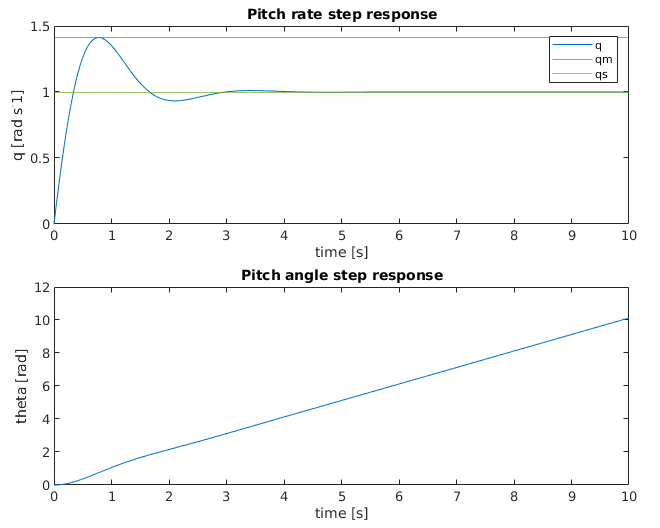


clf
layout = tiledlayout(2, 1, 'TileSpacing','compact', "Padding", "compact");

nexttile
plot(t, y(:, 1));

yline(qm, "Color", [0.8500, 0.3250, 0.0980])
yline(qs, "Color", [0.4660, 0.6740, 0.1880])

xlim([0, t_end]);
xlabel('time [s]')
ylabel('q [rad s^-1]')
title({'Pitch rate step response'})
legend("q", "qm", "qs")

nexttile
plot(t, y(:, 2));
xlabel('time [s]')
ylabel('theta [rad]')
title({'Pitch angle step response'})

xlim([0, t_end]);
set(gcf,'units','points','position',[0,0, 500, 400])

clf
hold on
GIB_allowed_area = [0 1; 0.3 1; 0.06 3; 0 3; 0 1]

GIB_allowed_area =          0    1.0000
    0.3000    1.0000
    0.0600    3.0000
         0    3.0000
         0    1.0000


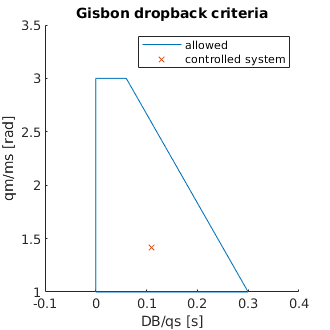

plot(GIB_allowed_area(:,1), GIB_allowed_area(:,2))
plot(DBqss, qm_qs, "x");

ylim([1, 3.5]);
xlim([-0.1, 0.4]);
xlabel('DB/qs [s]');
ylabel('qm/ms [rad]');
title({'Gisbon dropback criteria'})
legend("allowed", "controlled system")

set(gcf,'units','points','position',[0,0, 250, 250])